file_path1 = 'C:\Users\gajapathy.s\Desktop\gps\gps_occ.bag';
file_path2 = 'C:\Users\gajapathy.s\Desktop\gps\gps_open_still.bag';


% file_path3 ='C:\Users\gajapathy.s\Desktop\gps\gps_occ_walking.bag'


alt(file_path1,file_path2)

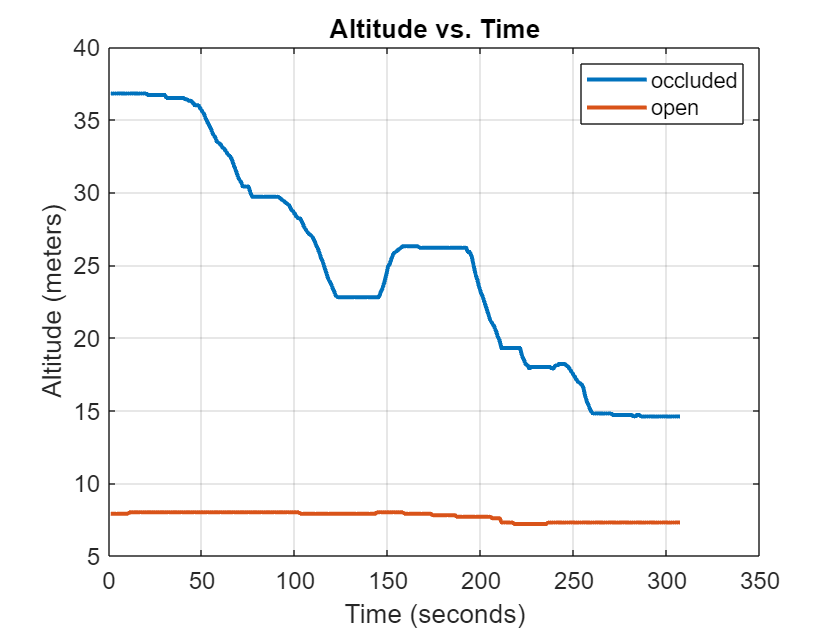

hold off

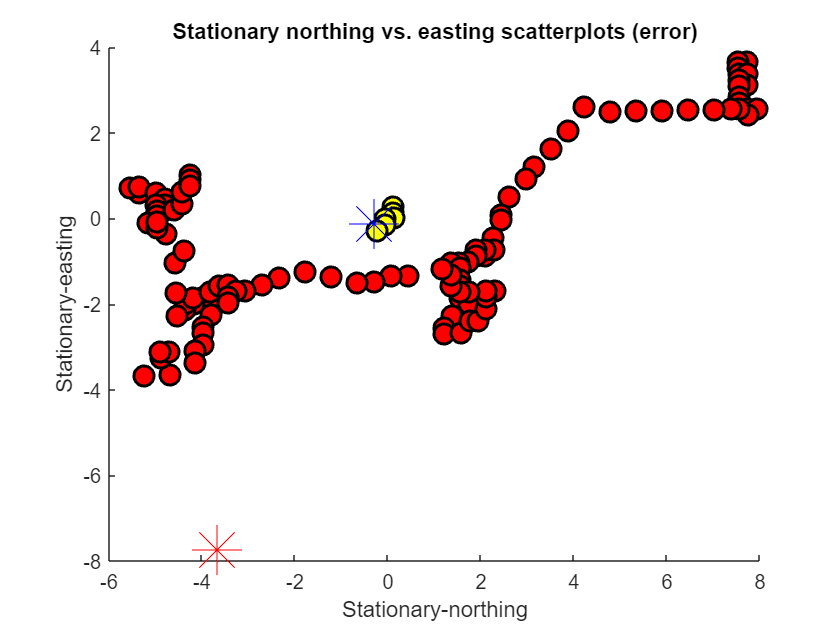

scatter_plot_error(file_path1,file_path2)
hold off

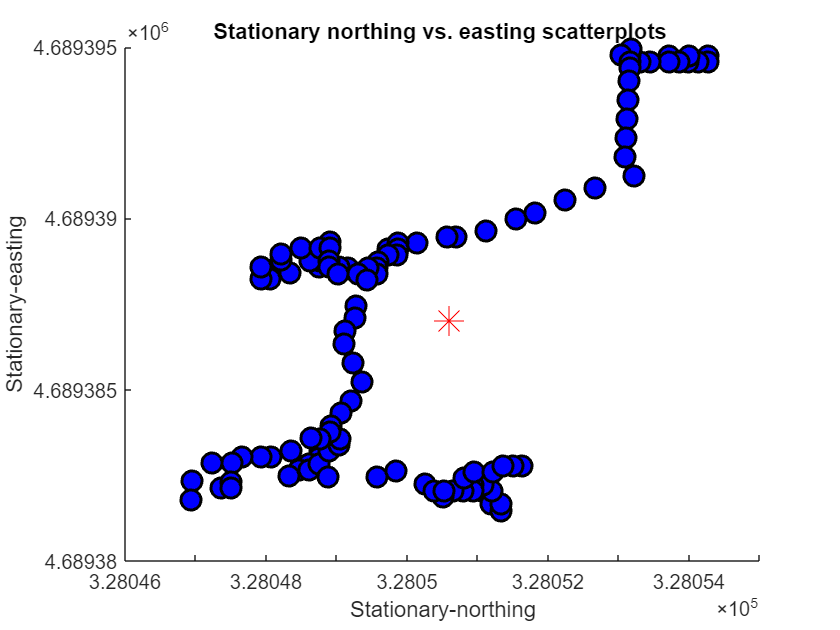

scatter_plot_n_e(file_path1,'b')

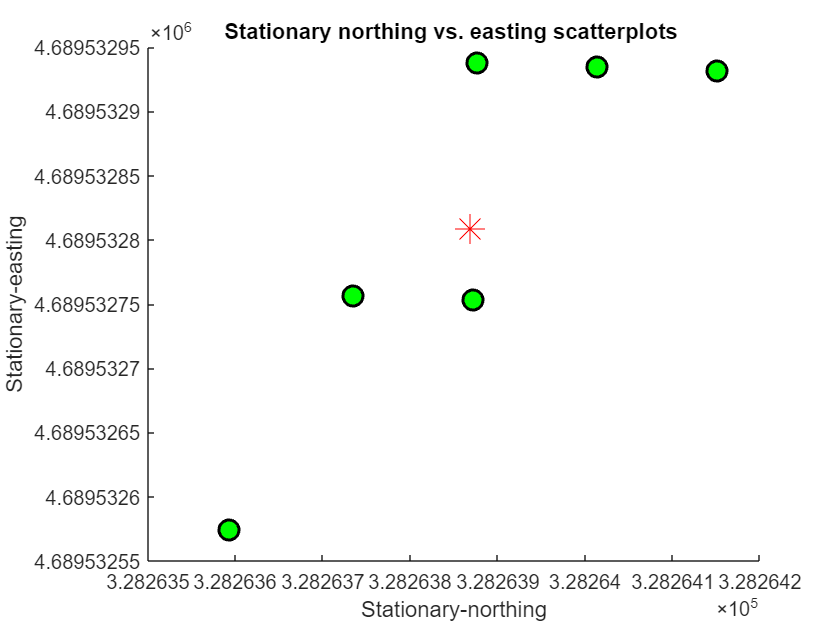

scatter_plot_n_e( file_path2,'g')

Euclidean_distance =     8.5521    8.5521    8.5521    8.5521    8.5521    8.5521    8.5521    8.5521    8.5521    8.5521    8.5521    8.5521    8.5521    8.5521    8.5521    8.5521    8.5521    8.5521    8.5521    8.5521    8.5521    8.5521    8.5521    8.5521    8.5521    8.5521    8.5521    8.5521    8.5521    8.5521    8.5521    8.3832    8.3832    8.3832    8.3832    8.3832    8.3832    8.3832    8.3832    8.3832    8.3832    8.3273    8.4442    8.2732    8.4442    8.3441    8.2211    8.2211    8.1709    8.0767


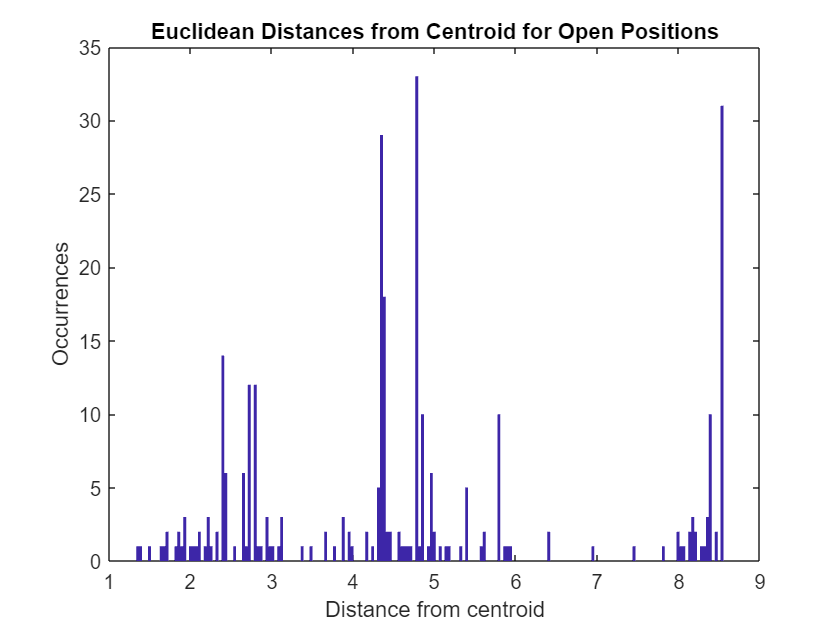

Euclidean_distance =     0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082    0.3082


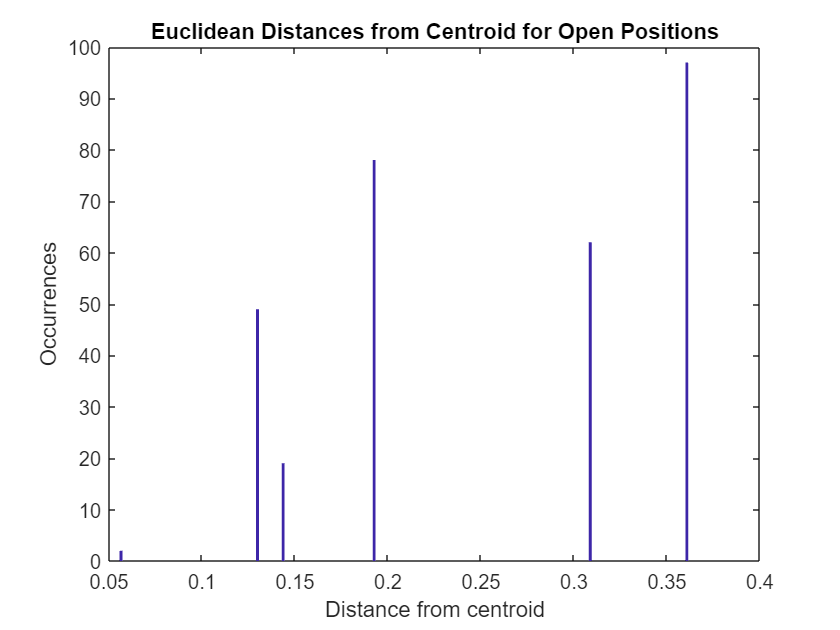

Euclidean_dis(file_path1,file_path2)

function []= alt(file_path1,file_path2)
 [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN]= extract_bag(file_path1);
 altitude_(Alt,delta_time);
 hold on
  [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN]= extract_bag(file_path2);
 altitude_(Alt,delta_time);

function[]= altitude_(Alt,delta_time)

t = 1:1:delta_time;

plot(t, Alt,"LineWidth",2.0 ); 

xlabel('Time (seconds)');
ylabel('Altitude (meters)');
title('Altitude vs. Time');
legend("occluded","open")

grid on;

set(gca, 'FontName', 'Arial', 'FontSize', 12);
set(gcf, 'Color', 'w'); 

end
end




function []= scatter_plot_error(file_path1,file_path2)

 [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN]= extract_bag(file_path1);
 scatterplot(UE,UN,'r');
 CutmE=mean(UE);
CutmN=mean(UN);
 hold on
plot(CutmE, CutmN, 'r*', 'MarkerSize', 25)
 hold off

 hold on
 [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN]= extract_bag(file_path2);
 scatterplot(UE,UN,'y');
 CutmE=mean(UE);
CutmN=mean(UN);
 hold on
plot(CutmE, CutmN, 'b*', 'MarkerSize', 25)
 hold off

xlabel('Stationary-northing');
ylabel('Stationary-easting');
title('Stationary northing vs. easting scatterplots (error)');

% legend("close","open")

function []=scatterplot(UE,UN,c)
CutmE=mean(UE);
CutmN=mean(UN);

Stationary_northing=UE-CutmE;
Stationary_easting=UN-CutmN;
scatter(Stationary_easting, Stationary_northing, 'Marker', 'o', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', c, 'SizeData', 100, 'LineWidth', 1.5, 'DisplayName', 'Data Points');

end
end




function []= scatter_plot_n_e(file_path,c)

 [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN]= extract_bag(file_path);
 scatter(UtmE, UtmN, 'Marker', 'o', 'MarkerEdgeColor', 'k', 'MarkerFaceColor', c, 'SizeData', 100, 'LineWidth', 1.5, 'DisplayName', 'Data Points');
CutmE=mean(UtmE);
CutmN=mean(UtmN);
 hold on
plot(CutmE, CutmN, 'r*', 'MarkerSize', 15)
 hold off

xlabel('Stationary-northing');
ylabel('Stationary-easting');
title('Stationary northing vs. easting scatterplots ');


end


% function [] = latlongplot(lat,long)
% 
% plot(long,lat)
% xlabel('longitude');
% ylabel('latitude');
% title('latitude vs longitude');



% % latlongplot(lat,long)
%  [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN]= extract_bag(file_path);
% 
% hold on
% 
% hold off
% 
% % latlongplot(lat,long)
% 
% end



function [] =Euclidean_dis(file_path1,file_path2)

 [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN]= extract_bag(file_path1);

 e_d(UE,UN)

 [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN]= extract_bag(file_path2);

 e_d(UE,UN)



function [] = e_d(UE,UN)

  open_positions = [UE;UN] ;

open_centroid = [mean(open_positions(1,:)); mean(open_positions(2,:))];

diff=open_positions-open_centroid;



Euclidean_distance = sqrt(((diff(1,:)).^2)+((diff(2,:)).^2))


figure;
hist(Euclidean_distance, 200, 'FaceColor', 'g', 'EdgeColor', 'k');

title('Euclidean Distances from Centroid for Open Positions');

 xlabel('Distance from centroid');
 ylabel('Occurrences')


    end

end

function [lat,long,Alt,UtmE,UtmN,delta_time,UE,UN]= extract_bag(file_path)
Alt=0;
lat=0;
long=0;
Alt=0;
UtmE=0;
UtmN=0;
delta_time=0;

bag = rosbag(file_path);
bSel = select(bag,'Topic','/chatter');
msgStructs = readMessages(bSel,'DataFormat','struct');

len=bSel.NumMessages;
S_time=bSel.StartTime;
E_time=bSel.EndTime;

delta_time=E_time-S_time;
delta_time=round(delta_time)+1;

for i=1:1:len
gps=msgStructs{i};
lat(i)=gps.Latitude;
long(i)=gps.Longitude;
Alt(i)=gps.Altitude;
UtmE(i)=gps.UtmEasting;
UtmN(i)=gps.UtmNorthing;

 UE(i)=UtmE(i)-UtmE(1);
 UN(i)=UtmN(i)-UtmN(1);

Z=gps.Zone;
L=gps.Letter;
H=gps.Hdop;
latD=gps.LatitudeDir;
lonD=gps.LongitudeDir;

end

end








